# Attitude control

Here we look at the steps from choosing attitude representation to attitude control strategy. We focus on the most common methods: Euler angles, rotation matrix, and quaternion. 

**Note: **You should  read previous chapters on drone equations of motions and attitude representations before preoceeding.

# Attitude representation

syms t
syms phi(t) theta(t) psi(t) p(t) q(t) r(t) % roll pitch yaw p q r
syms phi_dot(t)  theta_dot(t)  psi_dot(t) % euler rates
syms p_dot(t) q_dot(t) r_dot(t) % body rates
syms phi_t theta_t psi_t phi_dot_t theta_dot_t psi_dot_t % used to remove time dependence

#### Coordinate frames

- Inertial frame: NED. X-axis(roll) pointing forward(North), Y-axis(pitch) pointing right (east),Z-axis pointing down

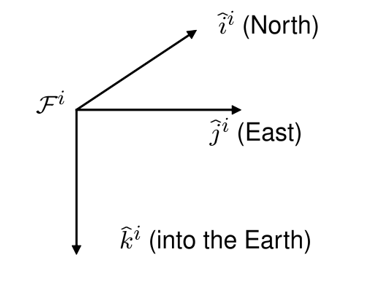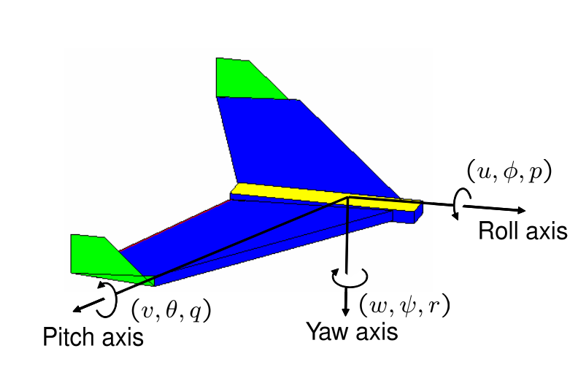

Let's use the Z - Y - X Euler angle convention

R1_z = [ 
      cos(psi),  -sin(psi),   0;
     sin(psi),  cos(psi),   0;
          0   ,     0    ,   1;
      
    ];
R2_y = [ 
         cos(theta) ,   0     , sin(theta);
            0       ,   1     ,     0    ;      
        -sin(theta)  ,   0     , cos(theta);
      
    ];
R3_x = [ 
         1   ,       0     ,     0      ;
         0   ,  cos(phi)   ,  -sin(phi);
         0   ,  sin(phi)  , cos(phi);   
    ];

### Body to world(inertial) frame rotation

wRb = R1_z*R2_y*R3_x % body to world

$$wRb(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & \cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)+\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\\ -\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

### World to body frame rotation

bRw=transpose(wRb) % world to body

$$bRw(t) = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & -\sin\left(\theta \left(t\right)\right)\\ \cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)+\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\\ \sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

### Euler angles from rotation matrix 

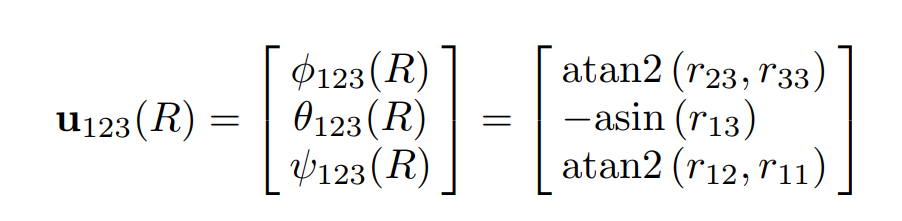

## Generate matlab function and simulink block for attitude representation

Rotation matrix

% remove time dependence form sym variables
cur_labels = [phi(t), theta(t), psi(t)];
new_labels = [phi_t, theta_t, psi_t];
bRw_new        = subs(bRw(t),cur_labels,new_labels);
wRb_new        = subs(wRb(t),cur_labels,new_labels);

INPUT_VAR_ORDER = {'phi_t', 'theta_t','psi_t'};
% matlab functions
matlabFunction(bRw_new,'File','generated/bRw', ...
              'Optimize',false, 'Vars', INPUT_VAR_ORDER);
matlabFunction(wRb_new,'File','generated/wRb', ...
              'Optimize',false, 'Vars', INPUT_VAR_ORDER);
% simulink blocks
SIM_FILENAME        = 'attitude_rep_blocks';
if exist(SIM_FILENAME,'file')==0
    new_system(SIM_FILENAME)
end
open_system(SIM_FILENAME)
BLOCK_NAME      = [SIM_FILENAME,'/bRw'];  
matlabFunctionBlock(BLOCK_NAME, bRw_new, ...
                    'Optimize',false, 'Vars', INPUT_VAR_ORDER);
BLOCK_NAME      = [SIM_FILENAME,'/wRb'];  
matlabFunctionBlock(BLOCK_NAME, wRb_new, ...
                    'Optimize',false, 'Vars', INPUT_VAR_ORDER);

# Angular rates

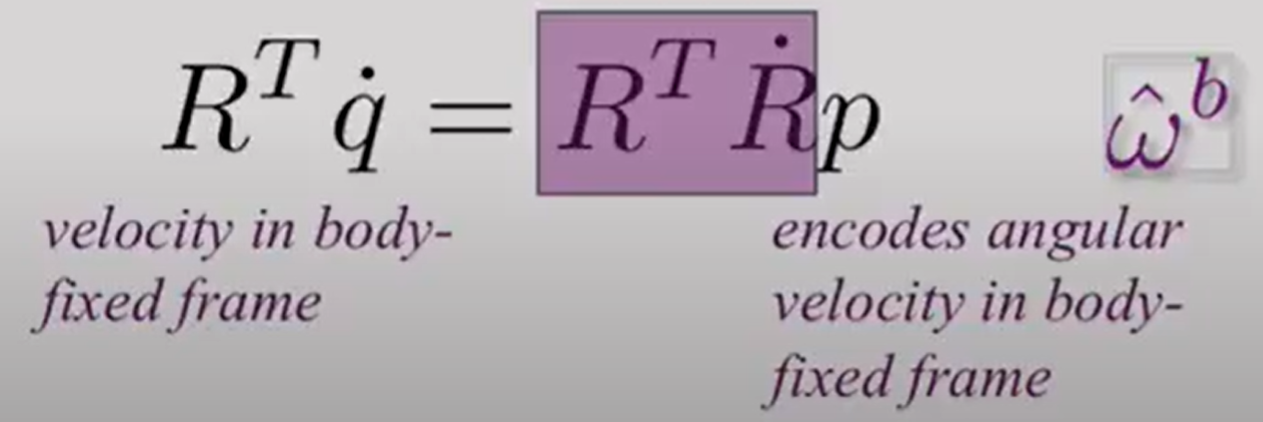   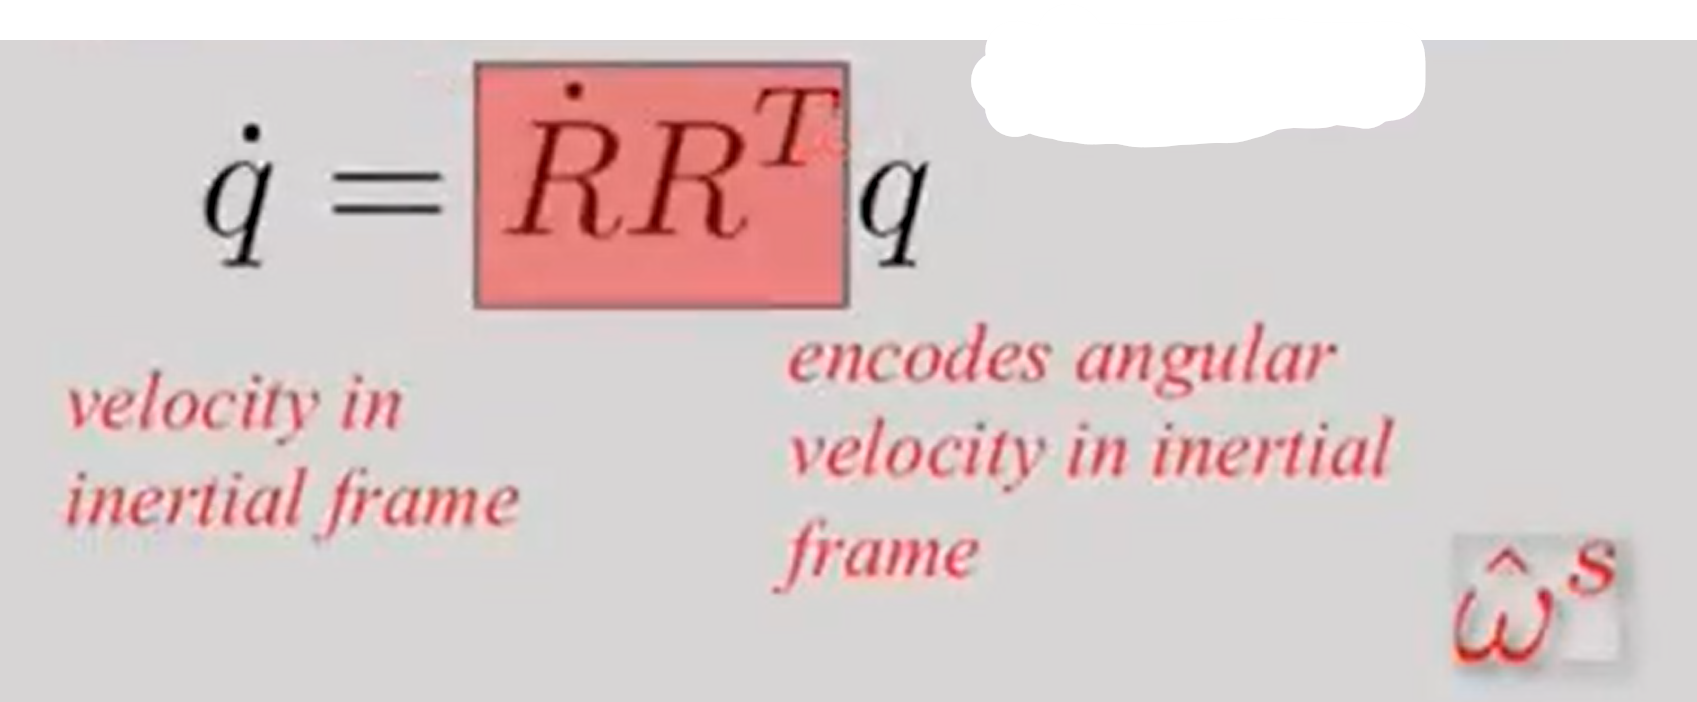

### Angulare velocity in body-fixed frame

R = wRb;
R_dot = simplify(diff(R,t));
omega_b = simplify(R.'*R_dot);
omega_b = omega_b(t)

Another manual way using $\omega_b ={\left(R_z R_x R_y \right)}^T *\left(\dot{\;R_z \;} R_x R_y +R_z \dot{\;\;R_x } R_y +R_z R_x \dot{\;\;R_y } \right)$

% another way to calculate it manually
w_b2 = simplify( (R1_z*R2_y*R3_x).'*(diff(R1_z,t)*R3_x*R2_y + R1_z*diff(R3_x,t)*R2_y + R1_z*R3_x*diff(R2_y,t)) )

### Angulare velocity in inertial frame

omega_w = simplify(R_dot*R.');
omega_w = omega_w(t)

### Euler rates to body rates conversion

Extract the vector from the skew-symmetric matrix (body-fixed frame)

w_x = simplify(omega_b(3,2));
w_y = simplify(omega_b(1,3));
w_z = simplify(omega_b(2,1));
wb = [w_x;w_y;w_z];

Substitute with shorter symbols

cur_labels = [phi(t), theta(t), psi(t),diff(phi(t), t), diff(theta(t), t),diff(psi(t), t) ];
new_labels = [phi_t, theta_t, psi_t, phi_dot_t, theta_dot_t, psi_dot_t];
wb_new = subs(wb,cur_labels,new_labels);
% simplify the expressions
wb_new = simplify(wb_new)

$$wb\_new = \left(\begin{array}{c} {\dot{\varphi }}_{t}-{\dot{\psi }}_{t}\,\sin\left(\theta_{t}\right)\\ {\dot{\theta }}_{t}\,\cos\left(\varphi_{t}\right)+{\dot{\psi }}_{t}\,\cos\left(\theta_{t}\right)\,\sin\left(\varphi_{t}\right)\\ {\dot{\psi }}_{t}\,\cos\left(\varphi_{t}\right)\,\cos\left(\theta_{t}\right)-{\dot{\theta }}_{t}\,\sin\left(\varphi_{t}\right) \end{array}\right)$$

Isolate the euler rates 

syms p q r  
x = [phi_dot_t, theta_dot_t, psi_dot_t].';
[A,b] = equationsToMatrix(  wb_new(1)==p, ...
                            wb_new(2)==q, ...
                            wb_new(3)==r, ...
                            x);
A

$$A = \left(\begin{array}{ccc} 1 & 0 & -\sin\left(\theta_{t}\right)\\ 0 & \cos\left(\varphi_{t}\right) & \cos\left(\theta_{t}\right)\,\sin\left(\varphi_{t}\right)\\ 0 & -\sin\left(\varphi_{t}\right) & \cos\left(\varphi_{t}\right)\,\cos\left(\theta_{t}\right) \end{array}\right)$$

The relashionship between body rates (pqr) and euler rates is:

### 
$$\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack =A*\left\lbrack \begin{array}{c}
\dot{\;\phi \;} \\
\dot{\;\theta \;} \\
\dot{\;\psi \;} 
\end{array}\right\rbrack$$


## Euler rates from our body rates 

Assuming the drone does NOT have a pitch angle of $\theta =\pm 90$, then we can use the results of the previous section to calculate the Euler rates from our body rates.

   
$$\left\lbrack \begin{array}{c}
\dot{\;\phi \;} \\
\dot{\;\theta \;} \\
\dot{\;\psi \;} 
\end{array}\right\rbrack =A^{-1\;} \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack =A^{-1} \omega_b$$


euler_rates = A \ [p; q; r];
euler_rates = simplify(euler_rates)

$$euler\_rates = \left(\begin{array}{c} \frac{p\,\cos\left(\theta_{t}\right)+r\,\cos\left(\varphi_{t}\right)\,\sin\left(\theta_{t}\right)+q\,\sin\left(\varphi_{t}\right)\,\sin\left(\theta_{t}\right)}{\cos\left(\theta_{t}\right)}\\ q\,\cos\left(\varphi_{t}\right)-r\,\sin\left(\varphi_{t}\right)\\ \frac{r\,\cos\left(\varphi_{t}\right)+q\,\sin\left(\varphi_{t}\right)}{\cos\left(\theta_{t}\right)} \end{array}\right)$$

## Generate matlab functions and simulink block for angular rates

% matlab function
FILENAME        = 'generated/euler_rates';
INPUT_VAR_ORDER = {'phi_t', 'theta_t', 'p', 'q', 'r'};
matlabFunction(euler_rates,'File',FILENAME, ...
              'Optimize',false, 'Vars', INPUT_VAR_ORDER);
% simulink block
SIM_FILENAME        = 'rates_blocks';
BLOCK_NAME      = [SIM_FILENAME,'/euler_rates'];
if exist(SIM_FILENAME,'file')==0
    new_system(SIM_FILENAME)
end
open_system(SIM_FILENAME)

matlabFunctionBlock(BLOCK_NAME, euler_rates, ...
                    'Optimize',false, 'Vars', INPUT_VAR_ORDER);

## Euler angles representation

This method has singularities however it is easy to understand and implement.

We discussed this representation in previous chapters and simulated a drone EOMs using this representation. In short, for stort from initial euler angles, conver the current body rates to euler rates using matrix A, then integrate to get euler angles. Rotation matrix from euler angles is construct to transform quantities between body and inertial frames.


$$\left\lbrack \begin{array}{c}
\dot{\;\phi \;} \\
\dot{\;\theta \;} \\
\dot{\;\psi \;} 
\end{array}\right\rbrack =A^{-1\;} \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$$



$$x_b ={}^bR_w\omega_w$$


## Rotation matrix representation

we can avoid  singularities in Euler angles representation by using rotation matrix representation. We will need both a rotation matrix $R$ that represents attitude and a rotation matrix derivative$\dot{\;R\;}$that represents the angular rates.

The following is the summary of the steps required to represent attitude (in world frame) using rotation matrix:

- Starting from body angular rates (pqr) $\omega_b$ which comes from sensors and state estimators.

- Start from intial attitude $R_0$ calculated from intial euler angles $\left(\phi_0 ,\theta_0 ,\psi_0 \right)$

- Convert body rates $\omega_b$ to angular rates in world frame $\omega_w$ using the rotation matrix $R$.  $\omega_w ={}^wR_b\omega_b$

- Represent the world angular rates using skew-symmetric matrix $\left\lbrack \omega_w \right\rbrack$

- Calculate the rotation matrix derivative using $\dot{R\;} =\left\lbrack \omega_w \right\rbrack \;{}^wR_b$

- Integrate $\dot{\;R}$ to get ${}^wR_b$and ensure it is still orthogonal

- Feed ${}^wR_b$ back to calculate $\omega_w$ in step 3.

 The implementation of this algorithm would look something like this:

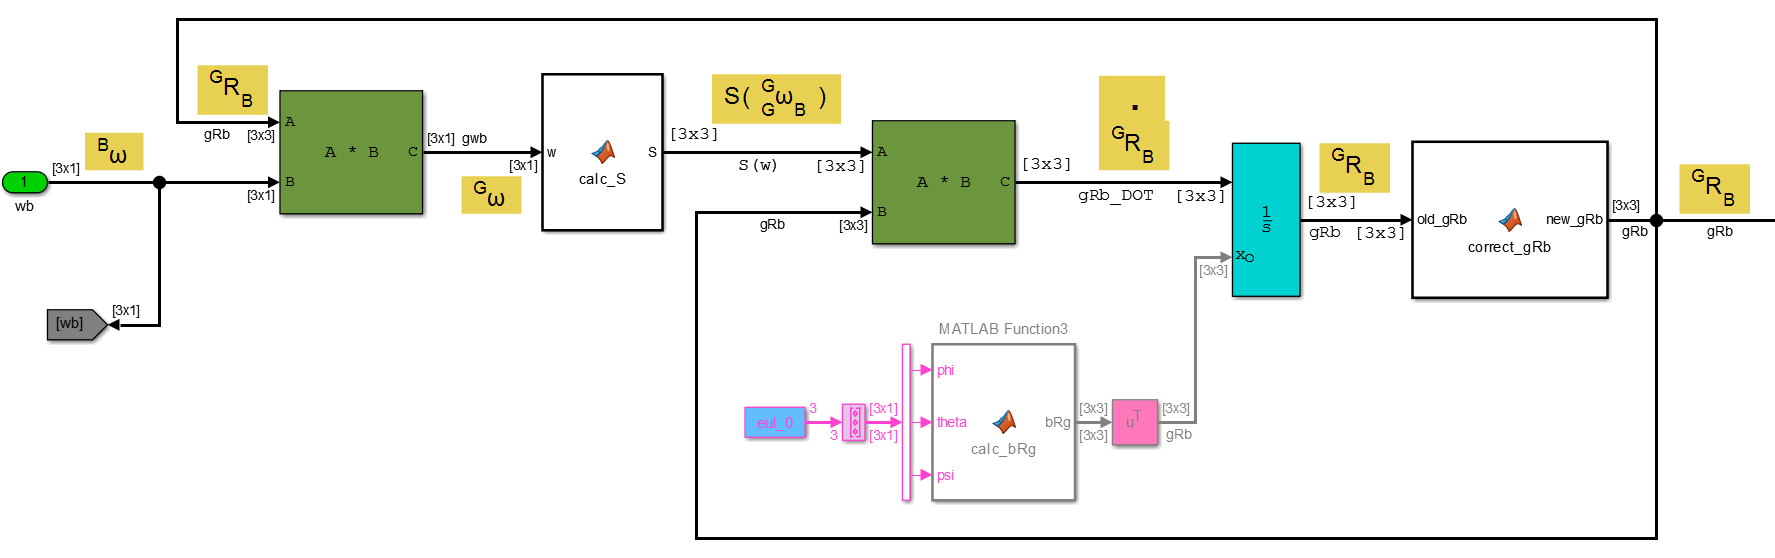

Note that to compute ${^gR_b}(t=0) }$, we could let the user specify an initial Euler angle configuration.  Also, the `calc_S` function would be:

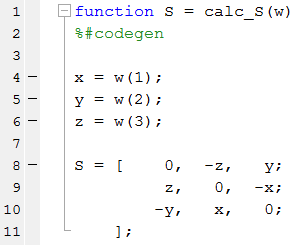

When we integrate ${\dot{ {^wR_b} }}$, we would expect that the orthogonality relationship of $\matrix{
  {^wR_b(t)} } \enspace . \thinspace {^wR_b(t)^T}= I 
}   $ would still  be true.  And it almost is !  The combination of "numerically" intergrating a derivative and the finite word size of computer calculations, means that we end up with a relationship that is more like this:

   
$$\matrix{
  {^wR_b(t)} } \enspace . \thinspace {^wR_b(t)^T}= I + \delta e \enspace \text{,where } \quad  \delta e \quad \text{ is a matrix of small terms}}
}   $$


We can reduce this $\delta e$ term using a correction technique such as the one proposed by William Premerlani and Paul Bizard (https://wiki.paparazziuav.org/w/images/e/e5/DCMDraft2.pdf).

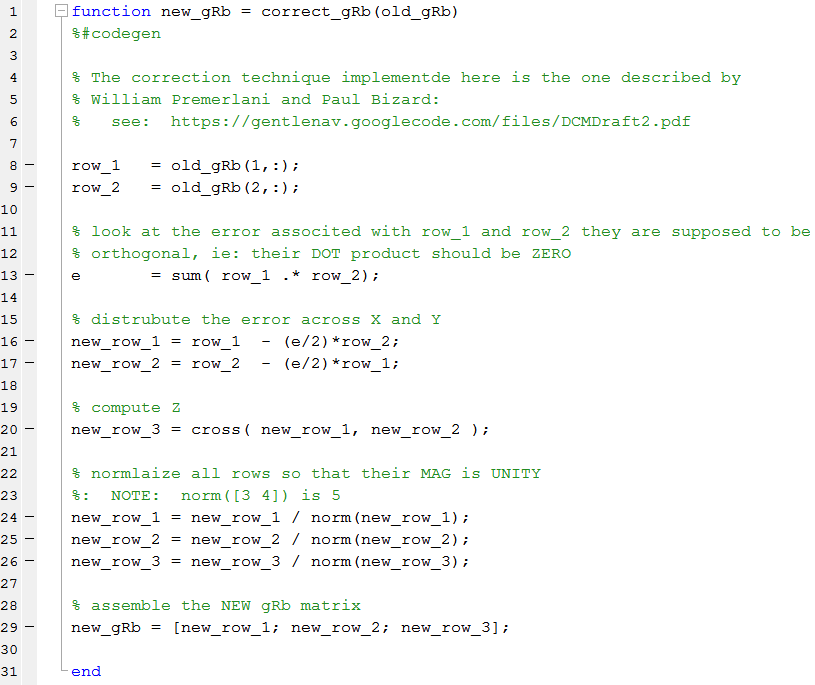

## Quaternion representation

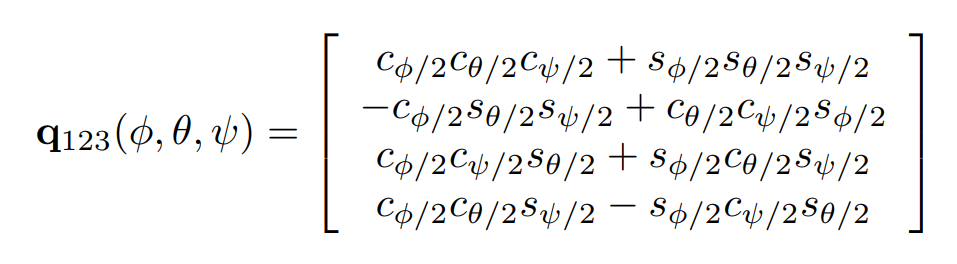

### Quaternion rates from body rates (body-fixed frame):


$$\dot{\;q} =\frac{1}{2}{W\left(q\right)}^T *\omega_b$$



$$W\left(q\right)=\left\lbrack \begin{array}{cccc}
-q_1  & q_0  & q_3  & -q_2 \\
-q_2  & {-q}_3  & q_0  & q_1 \\
-q_3  & q_2  & -q_1  & q_0 
\end{array}\right\rbrack$$


syms q0 q1 q2 q3 w1 w2 w3
w = [w1;w2;w3];
q = [q0;q1;q2;q3];
W = [-q1 q0 q3 -q2;
     -q2 -q3 q0 q1;
     -q3 q2 -q1 q0];
W_transpose = W.'

$$W\_transpose = \left(\begin{array}{ccc} -q_{1} & -q_{2} & -q_{3}\\ q_{0} & -q_{3} & q_{2}\\ q_{3} & q_{0} & -q_{1}\\ -q_{2} & q_{1} & q_{0} \end{array}\right)$$

q_dot = 0.5*W_transpose*w

$$q\_dot = \left(\begin{array}{c} -\frac{q_{1}\,w_{1}}{2}-\frac{q_{2}\,w_{2}}{2}-\frac{q_{3}\,w_{3}}{2}\\ \frac{q_{0}\,w_{1}}{2}+\frac{q_{2}\,w_{3}}{2}-\frac{q_{3}\,w_{2}}{2}\\ \frac{q_{0}\,w_{2}}{2}-\frac{q_{1}\,w_{3}}{2}+\frac{q_{3}\,w_{1}}{2}\\ \frac{q_{0}\,w_{3}}{2}+\frac{q_{1}\,w_{2}}{2}-\frac{q_{2}\,w_{1}}{2} \end{array}\right)$$

# Modelling actuators and mixing

### Rotation convention:

the following convention/propeller arrangement is assumed:

The motors are numbered clockwise: **front(1),right(2), back(3), left(4)**

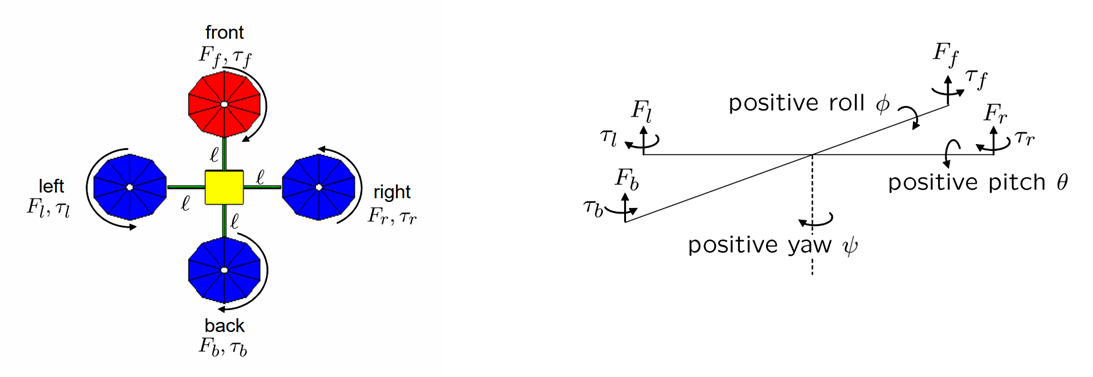

### Actuator modelling

The most common model of the propellers-motor pair is a proportional term to the angular velocity .

- Force/torque from each propeller is propertional to propeller rotation speed $f_i =k_t \omega_i^2 \;,m_i =k_m \omega_i^2$

-  Total thrust is summation of forces from all propellers (negative since Z-axis is pointing down) $F=-\sum_i k_t \omega_i^2 \;$

- Moment around x-axis (roll):$M_x =L\left(f_l -f_r \right)$

- Moment around y-axis (pitch): $M_y =L\left(f_f -f_b \right)$

- Moment around z-axis (yaw): from reactive torques, $M_z ={m_r +m}_l -{m_f -m}_b =k_m \left(\omega_r^2 \omega_l^2 -\omega_f^2 -\omega_b^2 \right)$

The mapping from angular velocities to twists(forces/moments) using allocation matrix C (this is called allocation or mixing):


$$\left\lbrack \begin{array}{c}
F\\
M
\end{array}\right\rbrack =C*\omega {\;}^2 \;$$
 


$$\left\lbrack \begin{array}{c}
F\\
M_x \\
M_y \\
M_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-k_t  & -k_t  & -k_t  & -k_t \\
0 & -Lk_t  & 0 & {\textrm{Lk}}_t \\
Lk_t  & 0 & -Lk_t  & 0\\
-k_m  & k_m  & {-k}_m  & k_m 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
\omega_f^2 \;\\
\omega_r^2 \\
\omega_b^2 \\
\omega_l^2 
\end{array}\right\rbrack \;$$
 

### Control

The control strategies will specify forces and torques. The actual motors commands can be found by inversing the allocation matrix


$$\omega {\;}^2 =C^{-1} \left\lbrack \begin{array}{c}
F\\
M
\end{array}\right\rbrack \;$$


syms L kt km w1 w2 w3 w4 thrust mx my mz
w_2 = [w1; w2; w3; w4]; % omega square
T = [thrust; mx; my;mz];

% construct the co-efficient matrix:
C = [
    -kt  ,   -kt   ,   -kt  ,   -kt  ;
    0    , -L*kt   ,   0    ,  L*kt  ;
   L*kt  ,   0     , -L*kt  ,    0   ;
    -km  ,   km    ,  -km   ,    km  ;
];

T == C *w_2

$$ans = \left(\begin{array}{c} \mathrm{thrust}=-\mathrm{kt}\,w_{1}-\mathrm{kt}\,w_{2}-\mathrm{kt}\,w_{3}-\mathrm{kt}\,w_{4}\\ \mathrm{mx}=L\,\mathrm{kt}\,w_{4}-L\,\mathrm{kt}\,w_{2}\\ \mathrm{my}=L\,\mathrm{kt}\,w_{1}-L\,\mathrm{kt}\,w_{3}\\ \mathrm{mz}=\mathrm{km}\,w_{2}-\mathrm{km}\,w_{1}-\mathrm{km}\,w_{3}+\mathrm{km}\,w_{4} \end{array}\right)$$

Using the inverse of allocation matrix to solve for motor commands

C_inv = inv(C)

$$C\_inv = \left(\begin{array}{cccc} -\frac{1}{4\,\mathrm{kt}} & 0 & \frac{1}{2\,L\,\mathrm{kt}} & -\frac{1}{4\,\mathrm{km}}\\ -\frac{1}{4\,\mathrm{kt}} & -\frac{1}{2\,L\,\mathrm{kt}} & 0 & \frac{1}{4\,\mathrm{km}}\\ -\frac{1}{4\,\mathrm{kt}} & 0 & -\frac{1}{2\,L\,\mathrm{kt}} & -\frac{1}{4\,\mathrm{km}}\\ -\frac{1}{4\,\mathrm{kt}} & \frac{1}{2\,L\,\mathrm{kt}} & 0 & \frac{1}{4\,\mathrm{km}} \end{array}\right)$$

w_2 == C_inv*T

$$ans = \left(\begin{array}{c} w_{1}=\frac{\mathrm{my}}{2\,L\,\mathrm{kt}}-\frac{\mathrm{thrust}}{4\,\mathrm{kt}}-\frac{\mathrm{mz}}{4\,\mathrm{km}}\\ w_{2}=\frac{\mathrm{mz}}{4\,\mathrm{km}}-\frac{\mathrm{thrust}}{4\,\mathrm{kt}}-\frac{\mathrm{mx}}{2\,L\,\mathrm{kt}}\\ w_{3}=-\frac{\mathrm{mz}}{4\,\mathrm{km}}-\frac{\mathrm{thrust}}{4\,\mathrm{kt}}-\frac{\mathrm{my}}{2\,L\,\mathrm{kt}}\\ w_{4}=\frac{\mathrm{mz}}{4\,\mathrm{km}}-\frac{\mathrm{thrust}}{4\,\mathrm{kt}}+\frac{\mathrm{mx}}{2\,L\,\mathrm{kt}} \end{array}\right)$$

matlabFunction(C_inv*T,'File','generated/control_allocation', ...
              'Optimize',false, 'Vars', [L,kt,km,thrust,mx,my,mz],'Outputs',{'w2_cmd'});

# Attitude control

The goal of the attitude control is to to ensure the drone attitude follows the desired one. Attitude control is highly dependent on how the attitude is represented, hence we will discuss three controllers that are used for the three common attitude representations discussed above (Euler angles, Rotation Matrix, Quaternion)

First, we need to formulate the error given the current and desired attitude. Then, we will formulate the command to drive the current attitude to the desired one as fast as possible. The output command represents the desired angular rates $\omega_d$ which are fed to the rate controller to regulate actuation torques.

## Control hierarchy

The common control hierarchies for attitude+rates are cascaded or single control approaches as follows:

### cascaded control

The attitude controller produces the commanded angular rates $\omega_d$ to the rate controller which in turn regulates the actuation torques. The actuation torques are combined with altitude controller that regulates altitude (height) through thrust $F_d$. The combined torques and thrust are fed to the motor controller and control allocation.

### Single control (attitude+angular rates)

The attitude controller operates directly on the drone torques by adding the attitude controller output to the rate controller to regulate the actuation torques. The actuation torques are combined with altitude controller that regulates altitude (height) through thrust $F_d$. The combined torques and thrust and fed to the motor controller and control allocation.

In our simulations we will use cascaded control similar to popular flight control systems such as Ardupilot and PX4.

An example of complete control architecture from PX4 flight stack is below. Note the use of quaternion to represent the attitude and cascading with angular rate controller

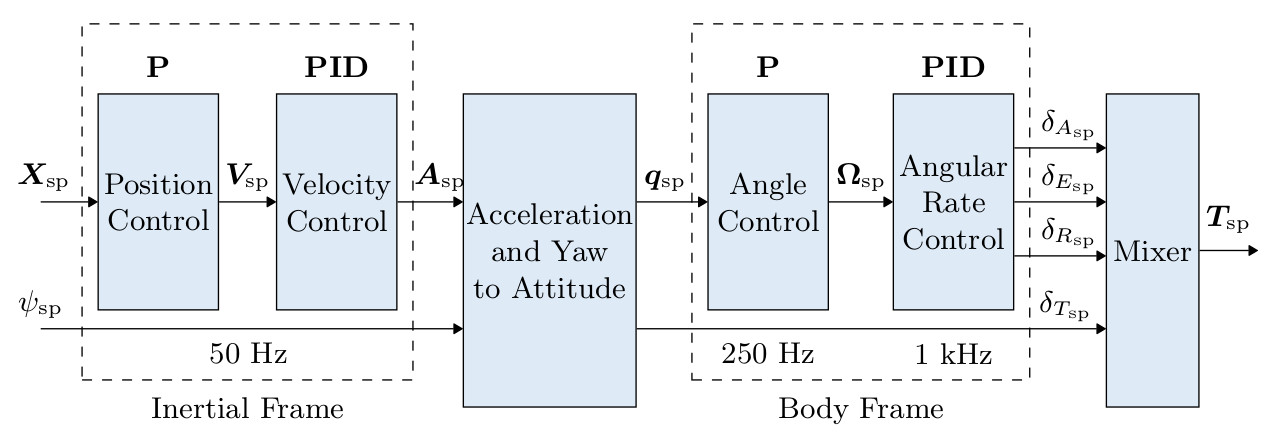

There are different approaches for realizing the error calculation of the attitude controller and hence the attitude controller output is also different. Each approach is suitable for different attitude represntation.

## Euler angles representation

### Error calculation

The error is easily the difference between desired angle and current angle


$$e_{\textrm{rpy}} =\left\lbrack \begin{array}{c}
e_{\phi } \\
e_{\theta } \\
e_{\psi } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\phi_c \\
\theta_c \\
\psi_c 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
\phi \;\\
\theta \;\\
\psi \;
\end{array}\right\rbrack$$


### control command

The attitude error can be used in a P-controller or P+D-controller to define the desired angular rates which is then fed to the rate controller. or The controller can command the the acuation torques directly 

#### 
$${\overrightarrow{\;\omega } }_d =k_{\textrm{rpy}} {\overrightarrow{\;e} }_{\textrm{rpy}} -k_{\textrm{dot}} \left\lbrack \begin{array}{c}
\dot{\;\phi } \;\\
\dot{\theta} \;\\
\dot{\psi} \;
\end{array}\right\rbrack$$


## Rotation matrix representation

**Note:** the rotation matrix refered below is the body to world rotation matrix

### Error calculation

The rotation matrix deviation$R_e$ is calculated by multiplying the transpose of desired rotation matrix ${R_d }^T$ by the current (estimated) rotation matrix $\hat{\;R\;}$.


$$R_e ={R_d }^T \hat{\;R\;}$$


The attitude error ${\overrightarrow{\;e} }_R$ can be found by calculating the axis around which to rotate the error vector that grows with the error angle 

#### 
$${\overrightarrow{\;e} }_R =\frac{1}{2}\left(R_e -R_e^T \right)=\frac{1}{2}\left({R_d }^T \hat{\;R\;} -{\hat{\;R\;} }^T R_d \right)$$


### control command

The attitude error can be used in a **P-controller **to define the desired angular rates which is then fed to the rate controller

#### 
$${\overrightarrow{\;\omega } }_d =k_R {\overrightarrow{\;e} }_R$$


## Quaternion representation

### Error calculation

The rotation error $q_e$ is calculated by multiplying the inverse of current (estimated) quaternion ${\hat{\;q\;} }^{-1}$ by the desired quaternion $q_d$  .


$$q_e ={\hat{\;q\;} }^{-1} \otimes q_d$$


The attitude error $q$ can be found by extracting the axis around which to rotate for correcting the attitude error and have this error vector grow with the error angle. This is achieve using hte vector componet of the quaternion ${\overrightarrow{q} }_e$  (i.e. $q=\left\lbrack \begin{array}{cc}
q_0  & \overrightarrow{q} 
\end{array}\right\rbrack$)

#### 
$${\overrightarrow{\;e} }_q =\textrm{sign}\left(q_{e,0} \right){\overrightarrow{q} }_e \;\;\;\textrm{with}\;\textrm{sign}\left(x\right)=\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;x\ge 0\\
-1 & \textrm{if}\;x<0
\end{array}\right.$$


**Note:** We needed to introduce the sign function to avoid the quaternion ambiguity (unwinding behavior) by using the anipodal quaternion such that the first element is always positive.

### control command

The attitude error can be used in a P-controller to define the desired angular rates which is then fed to the rate controller

#### 
$${\overrightarrow{\;\omega } }_d =k_q {\overrightarrow{\;e} }_q$$


## Rate control

The output from attitude control is the desired angular rates (pqr) which are regulated by rate controller. The controller is typically a PD controller unless the drone is operated in acro mode (no attitude controller), then an I-term is required.

The output of the rate controller is the desired torques which are fed to control allocation/mixer and motor controllers. 

### control command

#### 
$${\overrightarrow{\;\tau \;} }_d =\left\lbrack \begin{array}{c}
\tau_x \\
\tau_x \\
\tau_x 
\end{array}\right\rbrack =k_p {\overrightarrow{\;e} }_p -k_d \overrightarrow{\;\dot{\omega} \;}$$



$${\overrightarrow{\;e} }_p ={\overrightarrow{\;\omega } }_d -\overrightarrow{\;\omega }$$


where $\overrightarrow{\;\dot{\omega} \;}$ is estimated angular accelerations, $\overrightarrow{\;\omega }$ is current estimated angular velocit, $k_p ,k_d$ are control gains

## Steps:

#### 1- Control allocation:

- Force/moment from each propeller is propertional to propeller rotation speed $f_i =k_t \omega_i^2 \;,m_i =k_m \omega_i^2$

-  Total thrust and moments are calculated according to the allocation matrix C in previous section

- The inverse of allocation matrix ($\left.C^{-1} \right)$ is used for control since it maps the commanded thrust and moments to the commanded motor speeds which is fed to the motor control block

- for simulation purposes: the allocation matrix is used to simulate the mapping from motor speeds to generated thrusts and moments (mixing)

- **Inputs: **Commanded thrust and moments

- **Output**: commanded motor angular speeds

- **Parameters: **arm length (L), thrust and moment constants (kt and km)

#### 2- Linear motion (Netwon equation): 

- Convert from inertial motion  $m*a=F$ to body-fixed motion ${\mathrm{F}}_b =\mathrm{m}\ldotp \left(\dot{\;V_b } \;+\omega \times {\mathrm{V}}_b \right)$

- Rearrange equation to be have body linear acceleration $\dot{\;{\mathit{\mathbf{V}}}_{\mathit{\mathbf{b}}} }$ as output: $\dot{\;{\mathit{\mathbf{V}}}_{\mathit{\mathbf{b}}} } =\frac{{\mathit{\mathbf{F}}}_{\mathit{\mathbf{b}}} }{\mathit{\mathbf{m}}}-\left(\omega \times {\mathbf{V}}_{\mathit{\mathbf{b}}} \right)$

- The force vector consists of thrust from actuators and gravity force >> $\dot{\;{\mathit{\mathbf{V}}}_{\mathit{\mathbf{b}}} } =\frac{\left\lbrack \begin{array}{c}
0\\
0\\
{-F}_{\textrm{thrust}} 
\end{array}\right\rbrack +{}^bR_w\left\lbrack \begin{array}{c}
0\\
0\\
\textrm{mg}
\end{array}\right\rbrack }{\mathit{\mathbf{m}}}-\left(\omega \times {\mathbf{V}}_{\mathit{\mathbf{b}}} \right)$

- Integrate the linear acceleration to get linear velocity

- **Inputs: **the commanded thrust (from attitude control), body angular velocities (pqr) $\omega$ (step 3), ${}^bR_w$(step5)

- **Output**: ${\mathbf{V}}_{\mathit{\mathbf{b}}}$

- **Parameters: **mass (m), intital body-fixed velocity (default: $V_{\textrm{b0}} =\left\lbrack 0,0,0\right\rbrack$)

#### 3- Rotational motion (Euler equation):

- Represented in body-fixed frame: $I\dot{\;\omega } =M_b -\omega \times \left(I\omega \right)$ 

- Rearrange equation to get body angular acceleration($\dot{\;\omega }$) as output: $\dot{\;\omega } ={\mathit{\mathbf{I}}}^{-1} \left({\mathit{\mathbf{M}}}_{\mathit{\mathbf{b}}} -\omega \times \left(\mathit{\mathbf{I}}\omega \right)\right)$ 

- Integrate the body angular acceleration to get body-angular velocity (pqr)

- **Inputs: **the commanded Moments$M_b$ (from attitude control)

- **output**: $\omega \;$

- **Parameters: **inertia (I), intital body rates (default: $\omega_0 =\left\lbrack 0,0,0\right\rbrack$)

#### 4- Caculate Euler rates (Body to Inertial rates):

- Use the convertion matrix A  to conver body rates  $\omega =\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$to Euler rates 

- 
$$\left\lbrack \begin{array}{c}
\dot{\;\phi \;} \\
\dot{\;\theta \;} \\
\dot{\;\psi \;} 
\end{array}\right\rbrack =A^{-1\;} \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$$


- Integrate to get Euler angles

- **Inputs: ** body rates ($\omega \;$) (step 3), Euler angles  (this step output)

- **Output**: Euler angles $\left(\phi ,\theta ,\psi \right)$

- **Parameters: **intitial attitude default:$\left(\phi_0 ,\theta_0 ,\psi_0 \right)$=$\left(0,0,\psi_0 \right)$

#### 5- Caculate rotation matrix from euler angles:

- Use bRw formulated in the first section above to convert Euler angles to DCM

- **Inputs:** Euler angles $\left(\phi ,\theta ,\psi \right)$(step 4)

- **Output: ** rotation matrix ${}^bR_w$

- **Parameters: **

#### 6- Caculate inertial position and velocity:

- Use wRb formulated in the first section to convert body-fixed velocity $V_b$ in step 2 to inertial velocity $V$

- Integrate to get inertial position $p$ (NED xyz)

- **Inputs:** ${}^wR_b={}^bR^T_w$(step 5),  body-fixed velocity $V_b$(step 2)

- **Output: ** inertial positon and velocity $V,p$

- **Parameters: **initial position (default $p\left\lbrack 0,0,0\right\rbrack$)

#### 7- Attitude control:

- **Inputs:** commanded attitude, Euler angles $\left(\phi_c ,\theta_c ,\psi_c \right)$

- **Output: **commanded thrust and moments (goes to allocation matrix in step 1)

- **Parameters: None**

# Simulations

## Drone parameters

clear all;
run("quad_params.m")

## Euler angles attitude control

open_system("three_a_attitude_control_euler.slx")

## DCM attitude control

open_system("three_b_attitude_control_rotationMatrix.slx")

## Quaternion attitude control

open_system("three_c_attitude_control_quaternion.slx")

# References

Randal Beard, Quadrotor Dynamics and Control Rev 0.1, 2008

Quaternion based Estimation and Control for Attitude Tracking of a Quadcopter using IMU sensors, Matthias Grob  2016